# **META 3**

16. Carregue a estrutura de dados guardada no último ponto da meta anterior

dados = load("dados.mat").dados;

17. Considerando as melhores características extraídas dos sinais no tempo e frequência nos pontos 8 e 14, respetivamente, aplique um classificador para a identificação automatizada dos dígitos através das características extraídas. Para o efeito deverá usar um modelo à sua escolha (por exemplo Minimum Distance ou um sistema de regras if/else) utilizando como features as características extraídas dos sinais no tempo e frequência nos pontos 8 e 14. Guarde na sua estrutura de dados o resultado da classificação.

% Criar matriz de features diretamente a partir do struct
features = [... 
    [dados.energiaTotal]'         ...
    [dados.taxaCruzamentoZeros]'  ...
    [dados.razaoAmplitude]'       ...
    [dados.par]'                  ...
    [dados.entropia]'             ...
    [dados.spectralSlope]'];

% Obter vetor de digitos reais
digitoReal = [dados.digito]';

% Calcular centroides (médias) das features por dígito
centroides = zeros(10, 6);
for digito = 0:9
    idx = find(digitoReal == digito);
    centroides(digito + 1, :) = mean(features(idx, :), 1);
end

% Inicializar vetor para os dígitos previstos
digitoPrevisto = zeros(size(features, 1), 1);

% Calcular a distância mínima para cada amostra
for i = 1:size(features, 1)
    % Calcular a distância de cada amostra (i) para todos os centroides
    distancias = sqrt(sum((centroides - features(i, :)).^2, 2));
    
    % Encontrar o índice do centróide mais próximo (mínima distância)
    [~, digitoPrevisto(i)] = min(distancias);
end

% Ajustar para o digito correto (dígitos reais vão de 0 a 9)
digitoPrevisto = digitoPrevisto - 1;

% Guardar resultados no struct original
for i = 1:length(dados)
    dados(i).classificacao = digitoPrevisto(i);
end


18. Compare os dígitos atribuídos a cada áudio a partir do classificador usado no ponto anterior com os dígitos reais e defina a percentagem de acertos como: Acertos = Dígitos identificados corretamente Total de dígitos  100 Comente os resultados.

acertos = sum(digitoPrevisto == digitoReal);
total = length(digitoReal);
percentagemAcertos = acertos / total * 100;

19. Compare três tipos de janela diferentes, aplicando-as em intervalos de tempo. Qual é o efeito das diferentes janelas? Comente os resultados. 

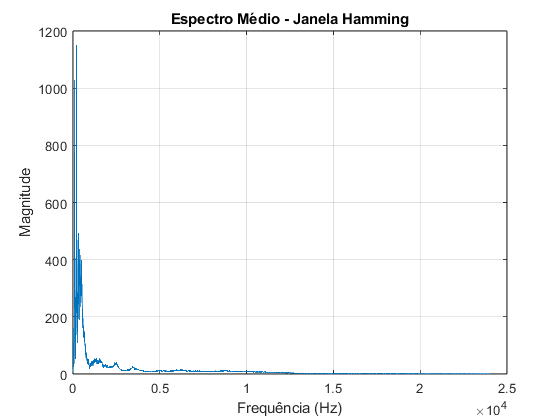

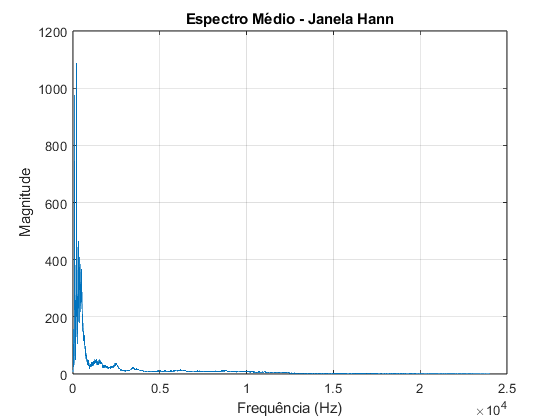

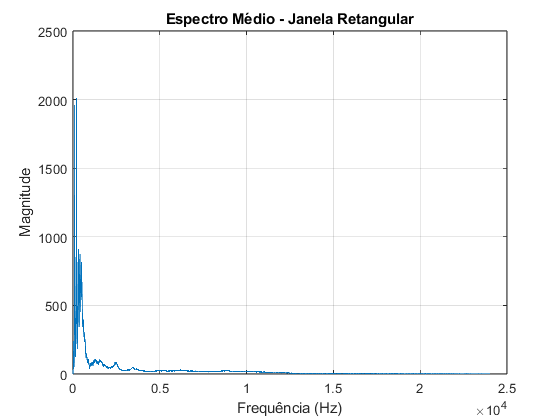

janelas = {@hamming, @hann, @(N) ones(N, 1)};
nomes = {'Hamming', 'Hann', 'Retangular'};

for j = 1:length(janelas)
    janelaFunc = janelas{j};
    espectros = [];

    for i = 1:length(dados)  % Usar todos os dados
        sinal = dados(i).sinal;
        janela = janelaFunc(length(sinal));
        sinalJanela = sinal .* janela;

        espectro = abs(fft(sinalJanela));
        espectro = espectro(1:length(sinal)/2);  % Frequências positivas apenas
        espectros = [espectros; espectro'];
    end

    % Calcular o espectro médio
    mediaEspectro = mean(espectros, 1);
    freq = linspace(0, dados(1).taxaAmostragem / 2, length(mediaEspectro));

    figure;
    plot(freq, mediaEspectro);
    title(['Espectro Médio - Janela ', nomes{j}]);
    xlabel('Frequência (Hz)');
    ylabel('Magnitude');
    grid on;
end

20. Atualize o ficheiro “.mat” carregado no início da meta com a estrutura de dados atualizada.

save('dados.mat', 'dados');